clc;
close all;
clear variables;

## Creating a datastore for my images

folder_name = fullfile(pwd, 'data');
imds = imageDatastore(folder_name, 'LabelSource',"foldernames");

### Label data 

Get label from filename

imds.Labels = char(imds.Labels); % turn labes to char
N = length(imds.Files);
for i = 1:N
    filename = imds.Files{i}(length(folder_name) + 1:end);
    left_parenth_index = find(filename == ' ');
    label = filename(2:left_parenth_index - 1);
    if strcmp(label, 'prazna')
        label = 'E';
    elseif strcmp(label,'pune')
        label = 'F';
    end
    imds.Labels{i} = label;
end

Only full balls

full_ball_imds = subset(imds, [imds.Labels{:}] == 'F');

## Preprocessing images

target_size = [600, 600];
final_size = [600, 600];
sigma_r = 650;
sigma_s = 5;

full_ball_imds = shuffle(full_ball_imds);

preprocessed_imds = transform(full_ball_imds, @(x) imresize(x, target_size));

preprocessed_imds = transform(preprocessed_imds, @(x) imresize(x, final_size));

preprocessed_imds = transform(preprocessed_imds, @(x) rgb2gray(x));

% preprocessed_imds = transform(preprocessed_imds, @(x) imbilatfilt(x, sigma_r, sigma_s));

### Display preprocessed images

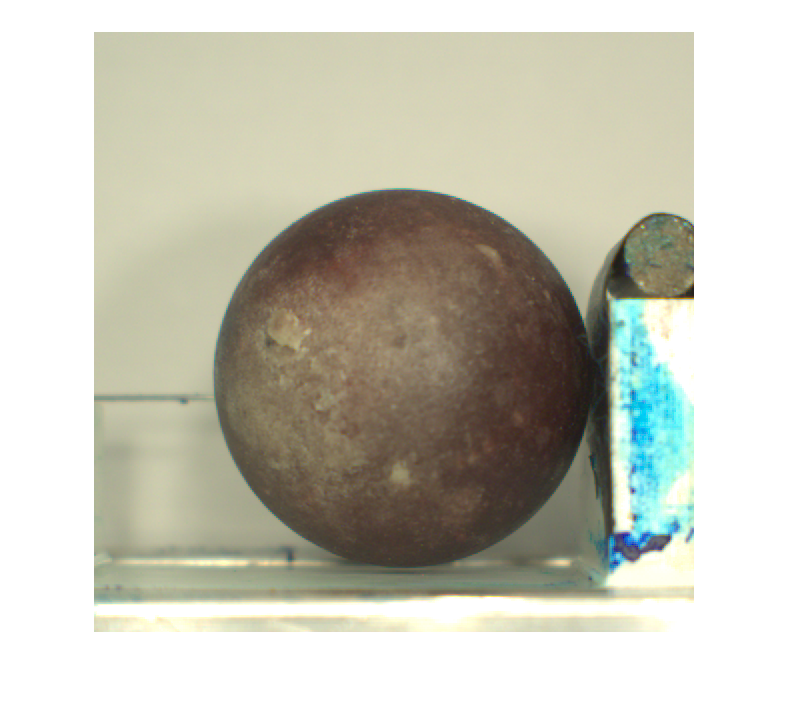

for i=1:1
    figure();
    original = preview(preprocessed_imds.UnderlyingDatastore);
    imshow(original)
end

[https://www.mathworks.com/help/images/detecting-a-cell-using-image-segmentation.html](https://www.mathworks.com/help/images/detecting-a-cell-using-image-segmentation.html)

original = preview(preprocessed_imds.UnderlyingDatastore);
figure();
imshow(original)
title("Original")
lab = rgb2lab(original);
hsv = rgb2hsv(original);
ntsc = rgb2ntsc(original);
xyz = rgb2xyz(original);
ycbcr = rgb2ycbcr(original);
gray = rgb2gray(original);

[centers,radii] = imfindcircles(original,[600/4 600/2],'ObjectPolarity','dark', ...
    'Sensitivity',0.96)

centers =   309.8434  347.9526


radii = 191.2869

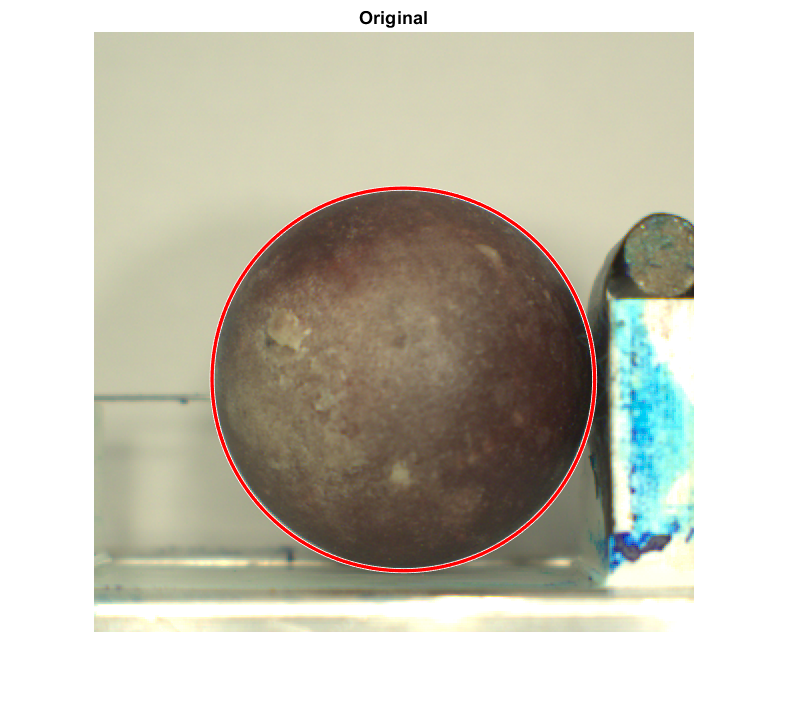

h = viscircles(centers,radii);

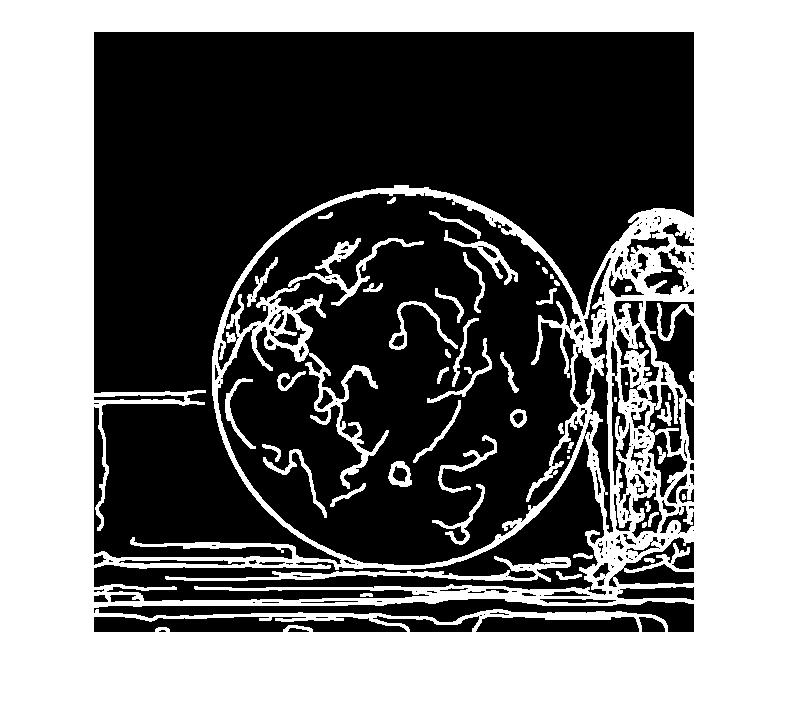

sens = 0.005;
G = lab;
G = imbilatfilt(G, 650, 5);
E = zeros(size(G, 1), size(G, 2), 'logical');
method = 'Canny';
for i=1:3
    E = E | edge(G(:, :, i), method);
end

se90 = strel('line',3,90);
se0 = strel('line',3,0);
E = imdilate(E,[se90 se0]);
figure();
imshow(E)

center = [300, 300]

center =    300   300


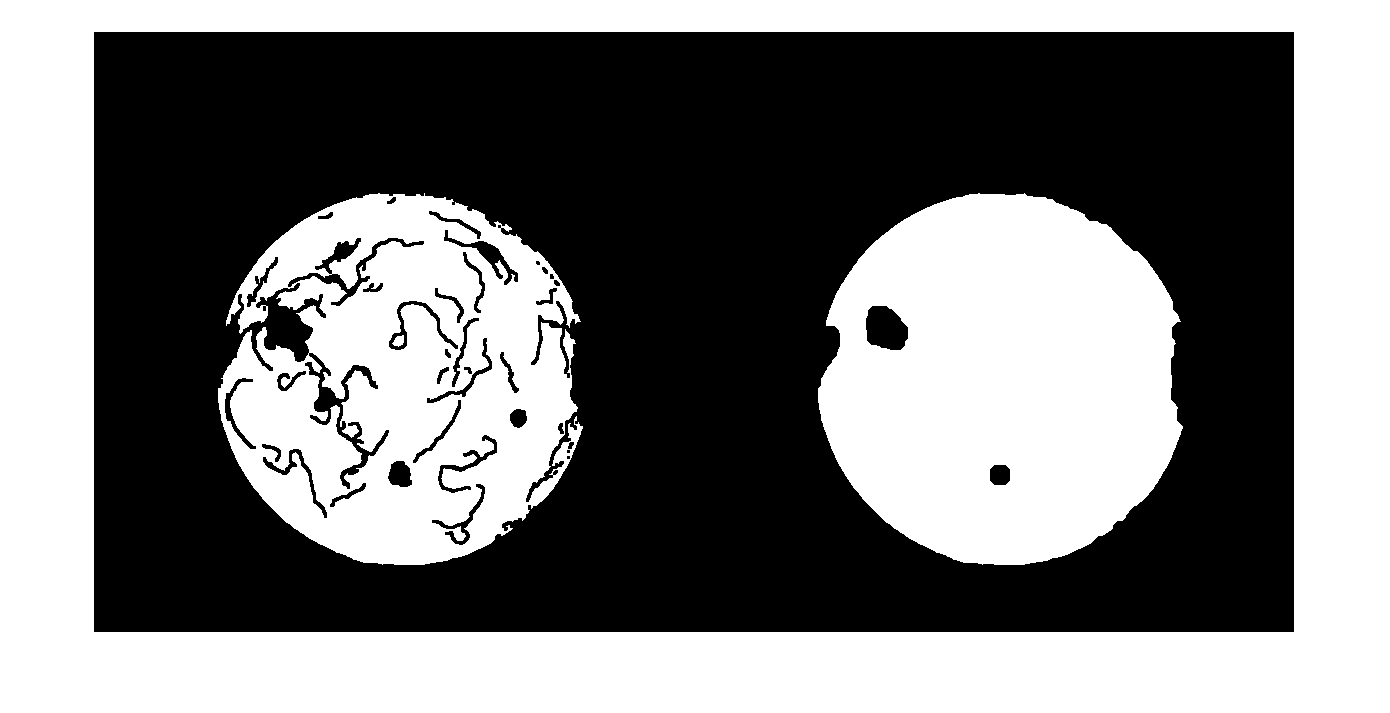

dev = 20;
F = imfill(E, center);
for i =1:100
    F = imfill(F, round(center + randn*dev));
end
F = F & (~E);
figure
imshowpair(F, imclose(F,se), 'montage')

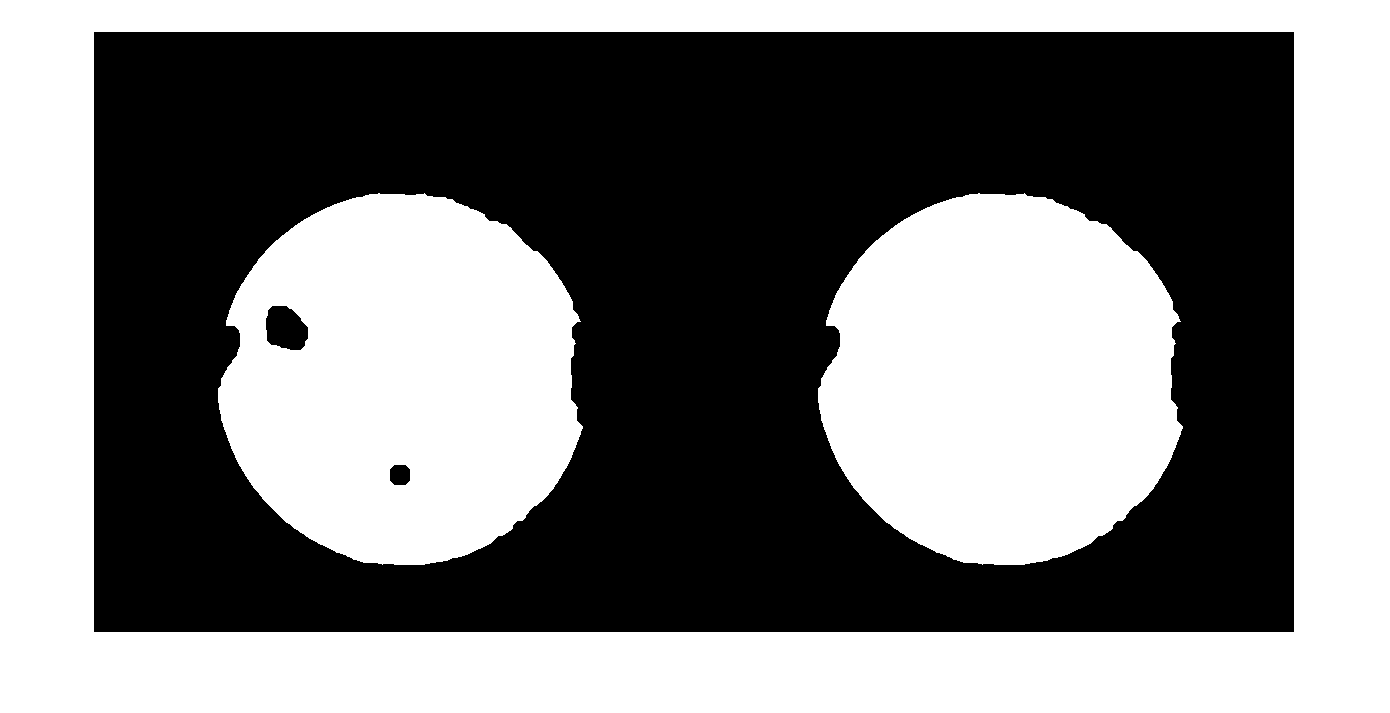


se = strel('disk',10);
F = imclose(F,se);
figure
imshowpair(F, imfill(F,'holes'), 'montage')

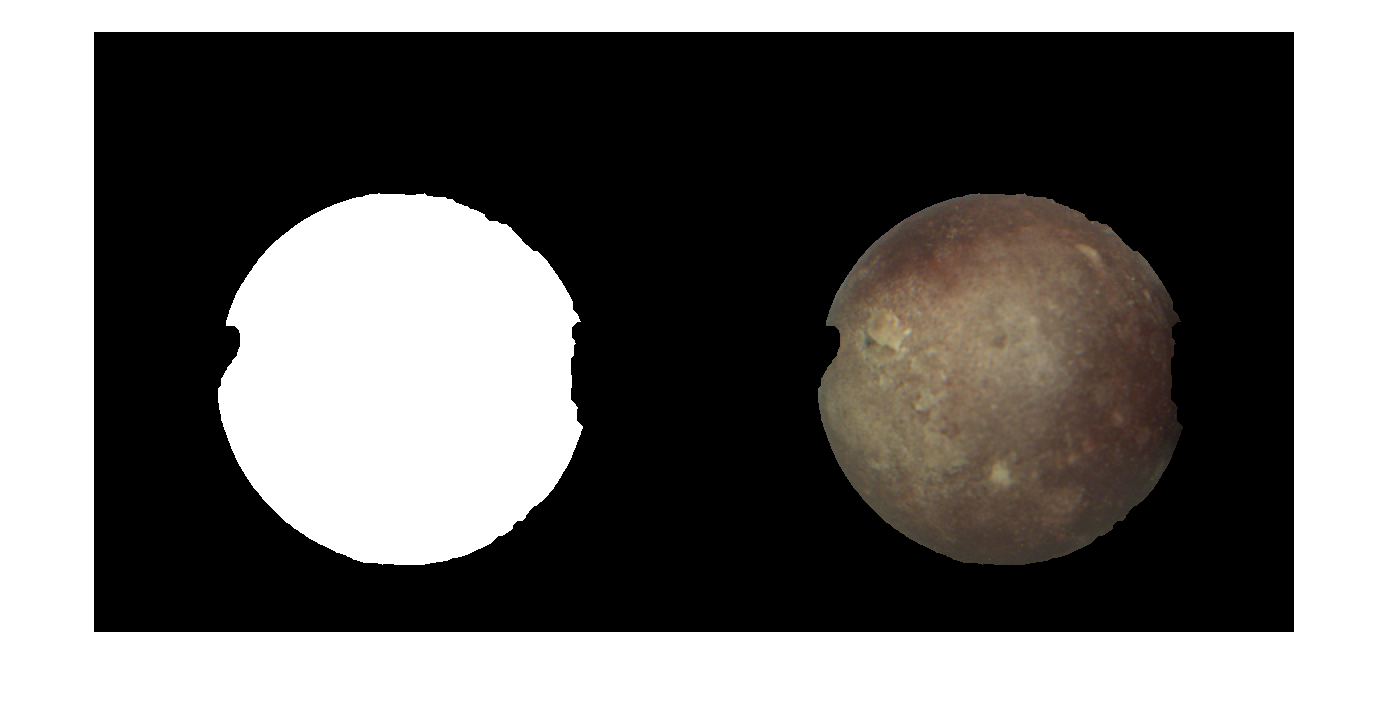

F = imfill(F,'holes');
segmented = uint8(F) .* original;
figure
imshowpair(F, segmented, 'montage')

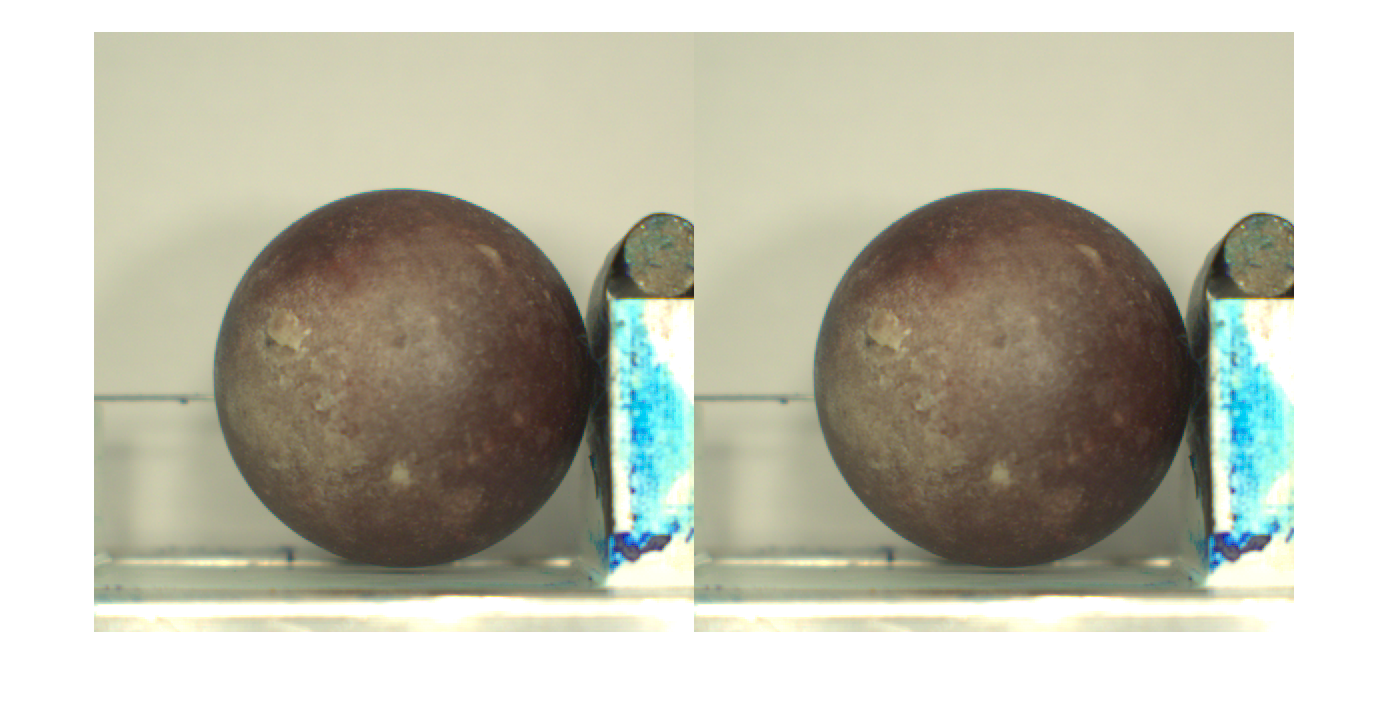


% TODO ici sa kruznom maskom i meriti varijansu, ako je varijansa mala onda
% je to vrv krug, ili mozda je najbolje da to bude ono Hough pa gledati
% vrednost maksimuma pa najveci maksiumi su krug a manji su defektni
figure()
imshowpair(original, segmented, 'montage')